%rotation with Eulero angles (moving axes)
%so R_YXZ = R_Y*R_X*R_Z
syms alpha real
syms beta real
syms gamma real

R_yxz = euler_rotation('yxz', [alpha beta gamma])

b = atan2(-sqrt(3)/2, 0.5)
a = atan2(0, (-0.5)/cos(b))
c = atan2(0.5/cos(b), 0)


a = rad2deg(a)
b=rad2deg(b)
c=rad2deg(c)

R = subs(R_yxz, {alpha, beta, gamma}, {deg2rad(180), deg2rad(-60), deg2rad(90)})

WR_B = R
BV_B = [1 -1 0]'
WR_B_dot = S(WR_B*BV_B)*WR_B

syms q1 real
syms q2 real
syms q3 real 

syms l0 real
syms l1 real
syms l2 real
syms l3 real

alpha = [-pi/2 -pi/2 0];
a=[-l1 -l2 -l3];
d=[l0 0 0];
theta=[q1 q2 q3];

table=[alpha',a',d',theta']

[T, A] = DHMatrix(table);
A0_1=A{1}
A1_2=A{2}
A2_2=A{3}
T
% how to obtain f_r, (i.e. r)
%{
    From DH table:
        A0_2 = A0_1 * A1_2 //mapping from frame 2 to frame 0
    So, to obtain the origin of frame 2 in frame 0:
        O2_2 = [0 0 0] % 3D space
            -> O2_2_H = [0 0 0 1] //homog. transf
        
        r = O0_2 = [rx ry rz 1]' = A0_2*O2_2_H 
%}
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2); f_r_3D(3)]

op = f_r 
wRo = [-1 0 0;0 0 1; 0 1 0]
wp = wRo * op 

syms q1 real
syms q2 real
syms q3 real 
syms q4 real 

syms l1 real
syms l2 real

alpha = [0 -pi/2 pi/2 0];
a=[l1 0 0 l2];
d=[0 0 q3 0];
theta=[q1 q2-pi/2 0 q4+pi/2];

table=[alpha',a',d',theta']

[T, A] = DHMatrix(table);
A0_1=A{1}
A1_2=A{2}
A2_2=A{3}
T
% how to obtain f_r, (i.e. r)
%{
    From DH table:
        A0_2 = A0_1 * A1_2 //mapping from frame 2 to frame 0
    So, to obtain the origin of frame 2 in frame 0:
        O2_2 = [0 0 0] % 3D space
            -> O2_2_H = [0 0 0 1] //homog. transf
        
        r = O0_2 = [rx ry rz 1]' = A0_2*O2_2_H 
%}
f_r_3D = get_f_r(T); %(X Y Z PHI)

f_r = [f_r_3D(1); f_r_3D(2); f_r_3D(4)]

j = simplify(jacobian(f_r, [q1 q2 q3 q4]))
j_ref_1 = get_rotation_mat(A0_1)' * j
minors = get_minors(j_ref_1, 3)
det_1 = det(simplify(minors{1}))
det_2 = det(simplify(minors{2}))
det_3 = det(simplify(minors{3}))
det_4 = det(simplify(minors{4}))

j_s = subs(j, {q1,q2,q3,q4}, {0, pi/2, 0, 0})
rank(j_s) 

## planar 2R Robot

syms q1 q2 dq1 dq2 'real'

% length l
l1=1
l2=1

% p in planar 2R
r=[l1*cos(q1)+l2*cos(q1+q2);
    l1*sin(q1)+l2*sin(q1+q2)]

% jacobian
J=jacobian(r,[q1 q2])

% time derivative of the Jacobian
Jder=[-l1*cos(q1)*dq1-l2*cos(q1+q2)*(dq1+dq2) -l2*cos(q1+q2)*(dq1+dq2);
    -l1*sin(q1)*dq1-l2*sin(q1+q2)*(dq1+dq2) -l2*sin(q1+q2)*(dq1+dq2)];

qa = [3*pi/4 -pi/2]'
qb = [pi/2 -pi/2]'
FA=(10/sqrt(2))*[1 1]'
j_qa = subs(J, [q1 q2], qa')
tau_a = j_qa' * FA 

j_qb = subs(J, [q1 q2], qb')
FB = (10/sqrt(2))*[-1 -1]'
tau_b = -j_qb' * FB

syms t T real
q1 = pi/4 + (pi/4)*(3*(t/T)^2-2*(t/T)^3)
q1_dot = diff(q1, {t})
q1_dot_dot = diff(q1_dot, {t})


q2 = -pi/2*(1-cos(pi*t/T))
q2_dot = diff(q2, {t})
q2_dot_dot = diff(q2_dot, {t})

q1_0 = subs(q1, {t}, {0})
q1_T = subs(q1, {t}, {T})

q2_0 = subs(q2, {t}, {0})
q2_T = subs(q2, {t}, {T})

q1_dot_0 = subs(q1_dot, {t}, {0})
q1_dot_T = subs(q1_dot, {t}, {T})

q2_dot_0 = subs(q2_dot, {t}, {0})
q2_dot_T = subs(q2_dot, {t}, {T})

q1_dot_dot_0 = subs(q1_dot_dot, {t}, {0})
q1_dot_dot_T = subs(q1_dot_dot, {t}, {T})

q2_dot_dot_0 = subs(q2_dot_dot, {t}, {0})
q2_dot_dot_T = subs(q2_dot_dot, {t}, {T})

q1_dot_dot_dot = diff(q1_dot_dot, {t})
q2_dot_dot_dot = diff(q2_dot_dot, {t})

clf
T=5
hold on
fplot(subs(q1_dot_dot), [0,T])
hold off 

clf
T=5
hold on
fplot(subs(q2_dot_dot), [0,T])
hold off 

clf
T=5
hold on
fplot(subs(q1_dot), [0,T])
hold off 

clf
T=5
hold on
fplot(subs(q2_dot), [0,T])
hold off 

syms t T real
q1 = pi/4 + (pi/4)*(3*(t/T)^2-2*(t/T)^3)
q1_dot = diff(q1, {t})
q1_dot_dot = diff(q1_dot, {t})

q2 = -pi/2*(1-cos(pi*t/T))
q2_dot = diff(q2, {t})
q2_dot_dot = diff(q2_dot, {t})

subs(q1_dot, {t}, {T/2})
subs(q2_dot, {t}, {T/2})

syms x gamma r real
eq = x^2 + (gamma*(x+0.8)^2)+1.1-r^2 == 0

$$eq = x^{2}-r^{2}+\gamma \,{\left(x+\frac{4}{5}\right)}^{2}+\frac{11}{10}=0$$

sol = solve(eq, x, 'ReturnConditions',true)

sol = struct with fields:
             x: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


s = sol.x

$$s = \left(\begin{array}{c} -\frac{8\,\gamma -5\,\sqrt{4\,\gamma \,r^{2}-\frac{174\,\gamma }{25}+4\,r^{2}-\frac{22}{5}}}{10\,\left(\gamma +1\right)}\\ -\frac{8\,\gamma +5\,\sqrt{4\,\gamma \,r^{2}-\frac{174\,\gamma }{25}+4\,r^{2}-\frac{22}{5}}}{10\,\left(\gamma +1\right)} \end{array}\right)$$

sol.parameters

 
ans =
 
Empty sym: 1-by-0
 


sol.conditions

$$ans = \left(\begin{array}{c} \gamma \neq -1\wedge 174\,\gamma +110\leq r^{2}\,\left(100\,\gamma +100\right)\\ \gamma \neq -1\wedge 174\,\gamma +110\leq r^{2}\,\left(100\,\gamma +100\right) \end{array}\right)$$

gamma = tan(deg2rad(-20))

gamma = -0.3640

r = 0.5+0.4

r = 0.9000

double(subs(s))

ans =     0.8040
    0.1116



x = double(subs(s(2)))

x = 0.1116

pw = [x; double(subs(gamma*(x+0.8)+1.1))]

pw =     0.1116
    0.7682



prv_1 = pw(1)+0.6*sin(deg2rad(20))

prv_1 = 0.3168

prv_2 = pw(2)-0.6*cos(deg2rad(20))

prv_2 = 0.2044



l1=0.5

l1 = 0.5000

l2=0.4

l2 = 0.4000

%% Inverse kinematic
% x of p and y of p
px= double(prv_1)

px = 0.3168

py= double(prv_2)

py = 0.2044


%%  q2
% second joint computations
c2=(px^2+py^2-l1^2-l2^2)/(2*l1*l2);
    s2pos=sqrt(1-c2^2);%simplify(sqrt(1-c2^2));  
    %other solution: -sqrt(1-c2^2)
    s2neg= -sqrt(1-c2^2);%simplify(-sqrt(1-c2^2));  

%% q1
% first joint computations
detM=l1^2+l2^2+2*l1*l2*c2;

% positive solution of q1
s1pos=(py*(l1+l2*c2)-px*l2*s2pos)/detM; %simplify((py*(l1+l2*c2)-px*l2*s2pos)/detM);
c1pos=(px*(l1+l2*c2)+py*l2*s2pos)/detM;%simplify((px*(l1+l2*c2)+py*l2*s2pos)/detM);

% negative solution of q1
s1neg=(py*(l1+l2*c2)-px*l2*s2neg)/detM;%simplify((py*(l1+l2*c2)-px*l2*s2neg)/detM);
c1neg=(px*(l1+l2*c2)+py*l2*s2neg)/detM;%simplify((px*(l1+l2*c2)+py*l2*s2neg)/detM);

% output positive
fprintf("Positive configuration\n")

Positive configuration


q01p=atan2(s1pos,c1pos);%simplify(atan2(s1pos,c1pos));
q02p=atan2(s2pos,c2);%simplify(atan2(s2pos,c2));
q0p=[q01p; q02p]

q0p =    -0.3345
    2.3046


    double(q0p)

ans =    -0.3345
    2.3046


%q0p=double([q01p; q02p])

fprintf("Negative configuration\n")

Negative configuration


% output negative
q01n=atan2(s1neg,c1neg);%simplify(atan2(s1neg,c1neg));
q02n=atan2(s2neg,c2);%simplify(atan2(s2neg,c2));
q0n =[q01n;q02n]

q0n =     1.4805
   -2.3046


    double(q0n)

ans =     1.4805
   -2.3046


qrv = q0n

qrv =     1.4805
   -2.3046



b = deg2rad(-20)

b = -0.3491

v_vers = [cos(b); sin(b)]

v_vers =     0.9397
   -0.3420



v=v_vers*0.3

v =     0.2819
   -0.1026



syms q1 q2 dq1 dq2 'real'

% length l
l1=0.5

l1 = 0.5000

l2=0.4

l2 = 0.4000


% p in planar 2R
r=[l1*cos(q1)+l2*cos(q1+q2);
    l1*sin(q1)+l2*sin(q1+q2)]

$$r = \left(\begin{array}{c} \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{2}\\ \frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}+\frac{\sin\left(q_{1}\right)}{2} \end{array}\right)$$


% jacobian
J=jacobian(r,[q1 q2])

$$J = \left(\begin{array}{cc} -\frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}-\frac{\sin\left(q_{1}\right)}{2} & -\frac{2\,\sin\left(q_{1}+q_{2}\right)}{5}\\ \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5}+\frac{\cos\left(q_{1}\right)}{2} & \frac{2\,\cos\left(q_{1}+q_{2}\right)}{5} \end{array}\right)$$


q1 = qrv(1)

q1 = 1.4805

q2 = qrv(2)

q2 = -2.3046

j_rv = subs(J)

$$j\_rv = \left(\begin{array}{cc} \frac{2\,\sin\left(\frac{1855628870113505}{2251799813685248}\right)}{5}-\frac{\sin\left(\frac{3333766676176955}{2251799813685248}\right)}{2} & \frac{2\,\sin\left(\frac{1855628870113505}{2251799813685248}\right)}{5}\\ \frac{\cos\left(\frac{3333766676176955}{2251799813685248}\right)}{2}+\frac{2\,\cos\left(\frac{1855628870113505}{2251799813685248}\right)}{5} & \frac{2\,\cos\left(\frac{1855628870113505}{2251799813685248}\right)}{5} \end{array}\right)$$

double(j_rv)

ans =    -0.2044    0.2936
    0.3168    0.2717



A = j_rv

$$A = \left(\begin{array}{cc} \frac{2\,\sin\left(\frac{1855628870113505}{2251799813685248}\right)}{5}-\frac{\sin\left(\frac{3333766676176955}{2251799813685248}\right)}{2} & \frac{2\,\sin\left(\frac{1855628870113505}{2251799813685248}\right)}{5}\\ \frac{\cos\left(\frac{3333766676176955}{2251799813685248}\right)}{2}+\frac{2\,\cos\left(\frac{1855628870113505}{2251799813685248}\right)}{5} & \frac{2\,\cos\left(\frac{1855628870113505}{2251799813685248}\right)}{5} \end{array}\right)$$

B = v

B =     0.2819
   -0.1026


q_rv_dot = linsolve(A,B)

$$q\_rv\_dot = \begin{array}{l} \left(\begin{array}{c} -\frac{20313596816708264\,\cos\left(\frac{1855628870113505}{2251799813685248}\right)+7393544592166489\,\sin\left(\frac{1855628870113505}{2251799813685248}\right)}{36028797018963968\,\sigma_{1}}\\ \frac{101567984083541320\,\cos\left(\frac{3333766676176955}{2251799813685248}\right)-36967722960832445\,\sin\left(\frac{3333766676176955}{2251799813685248}\right)+81254387266833056\,\cos\left(\frac{1855628870113505}{2251799813685248}\right)+29574178368665956\,\sin\left(\frac{1855628870113505}{2251799813685248}\right)}{144115188075855872\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{3333766676176955}{2251799813685248}\right)\,\sin\left(\frac{1855628870113505}{2251799813685248}\right)+\sin\left(\frac{3333766676176955}{2251799813685248}\right)\,\cos\left(\frac{1855628870113505}{2251799813685248}\right) \end{array}$$

double(q_rv_dot)

ans =    -0.7185
    0.4601


% cubic polynomial

## Q1

syms tau real
syms a b c d real
syms Dq real
syms qin qfin real
syms vin vfin real
syms T real

qn = a*tau^3 + b*tau^2 +c*tau + d 

$$qn = a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d$$

q = qin + Dq*qn

$$q = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$


eq_1 = a+b+c==1

$$eq\_1 = a+b+c=1$$

eq_2 = c==vin*T/Dq 

$$eq\_2 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

eq_3 = 3*a+2*b+c == vfin*T/Dq

$$eq\_3 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$


s = solve([eq_1, eq_2, eq_3], [a, b, c])

s = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]


a = simplify(s.a)

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

b = simplify(s.b)

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

c = simplify(s.c)

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$


%input
T = 2

T = 2


qin = pi

qin = 3.1416

qfin = 1.4805

qfin = 1.4805


vin = 0

vin = 0

vfin = -0.7185

vfin = -0.7185


Dq = double(qfin-qin);
a = double(subs(a))

a = -1.1349

b = double(subs(b))

b = 2.1349

c = double(subs(c))

c = 0

d = 0

d = 0


syms t real
q_t = subs(q, {tau}, {t/T})

$$q\_t = \mathrm{qin}+\mathrm{Dq}\,\left(\frac{a\,t^{3}}{8}+\frac{b\,t^{2}}{4}+\frac{c\,t}{2}+d\right)$$

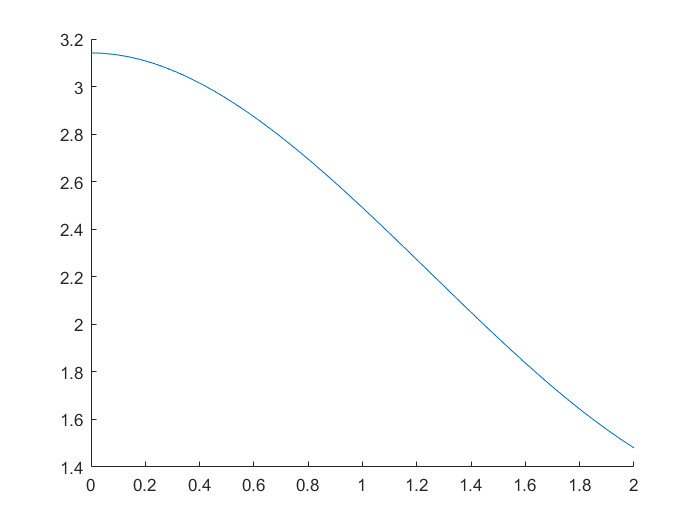

q_t = simplify(subs(q_t));

clf
hold on
fplot(q_t, [0,T])
hold off 

q_dot = diff(q_t, {t})

$$q\_dot = \frac{14338537717125850958202568576401\,t^{2}}{20282409603651670423947251286016}-\frac{8990882771090890996441888283099\,t}{5070602400912917605986812821504}$$

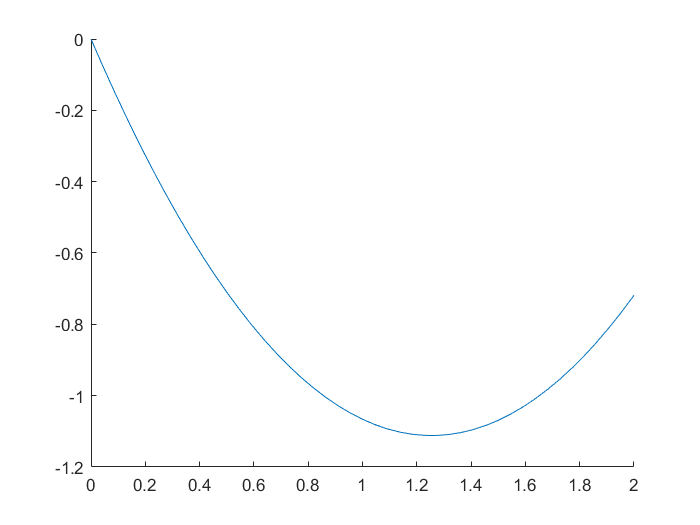


clf
hold on
fplot(q_dot, [0,T])
hold off 

## Q2

% cubic polynomial
syms tau real
syms a b c d real
syms Dq real
syms qin qfin real
syms vin vfin real
syms T real

qn = a*tau^3 + b*tau^2 +c*tau + d 

$$qn = a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d$$

q = qin + Dq*qn

$$q = \mathrm{qin}+\mathrm{Dq}\,\left(a\,\tau^{3}+b\,\tau^{2}+c\,\tau +d\right)$$


eq_1 = a+b+c==1

$$eq\_1 = a+b+c=1$$

eq_2 = c==vin*T/Dq 

$$eq\_2 = c=\frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$

eq_3 = 3*a+2*b+c == vfin*T/Dq

$$eq\_3 = 3\,a+2\,b+c=\frac{T\,\mathrm{vfin}}{\mathrm{Dq}}$$


s = solve([eq_1, eq_2, eq_3], [a, b, c])

s = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]


a = simplify(s.a)

$$a = \frac{T\,\mathrm{vfin}-2\,\mathrm{Dq}+T\,\mathrm{vin}}{\mathrm{Dq}}$$

b = simplify(s.b)

$$b = -\frac{T\,\mathrm{vfin}-3\,\mathrm{Dq}+2\,T\,\mathrm{vin}}{\mathrm{Dq}}$$

c = simplify(s.c)

$$c = \frac{T\,\mathrm{vin}}{\mathrm{Dq}}$$


%input
T = 2

T = 2


qin = 0

qin = 0

qfin = -2.3016

qfin = -2.3016


vin = 0

vin = 0

vfin = 0.4601

vfin = 0.4601


Dq = double(qfin-qin);
a = double(subs(a))

a = -2.3998

b = double(subs(b))

b = 3.3998

c = double(subs(c))

c = 0

d = 0

d = 0


syms t real
q_t = subs(q, {tau}, {t/T})

$$q\_t = \mathrm{qin}+\mathrm{Dq}\,\left(\frac{a\,t^{3}}{8}+\frac{b\,t^{2}}{4}+\frac{c\,t}{2}+d\right)$$

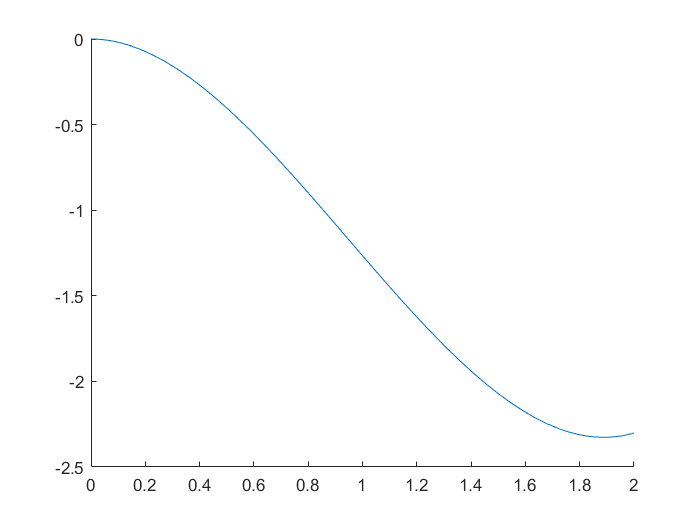

q_t = simplify(subs(q_t));

clf
hold on
fplot(q_t, [0,T])
hold off 

q_dot = diff(q_t, {t})

$$q\_dot = \frac{t\,\left(27617\,t-78250\right)}{20000}+\frac{27617\,t^{2}}{40000}$$

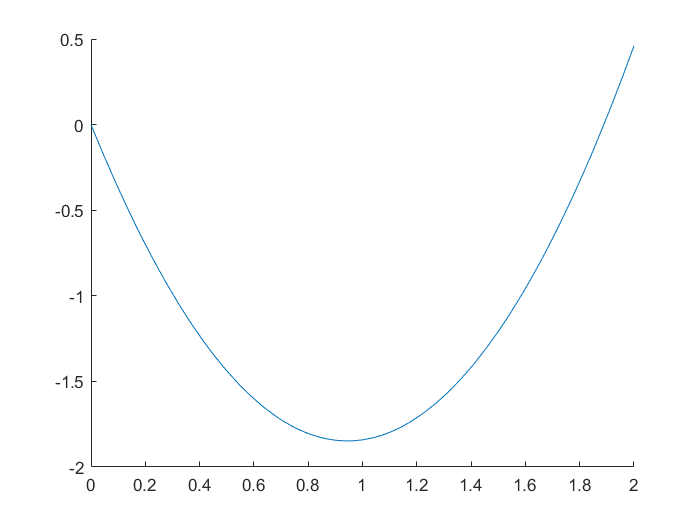


clf
hold on
fplot(q_dot, [0,T])
hold off 